# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.



% Initial end-effector pose
% taskInit = trvec2tform([[0.15 0.2 0.2]])*axang2tform([0 1 0 pi]); % Scene 1
taskInit = trvec2tform([[0.3 0.0 0.5]])*axang2tform([0 1 0 pi]); % Scene 2
% taskInit = trvec2tform([[0.1 0.4 0.3]])*axang2tform([0 1 0 pi]); % Scene 3
% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
% taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
% taskFinal = trvec2tform([0.25 -0.3 0.2])*axang2tform([0 1 0 pi]);   % Scene 1
taskFinal = trvec2tform([0.25 0.0 0.05])*axang2tform([0 1 0 pi]);   % Scene 2
% taskFinal = trvec2tform([[-0.1 0.4 0.3]])*axang2tform([0 1 0 pi]);   % Scene 3
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);


## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

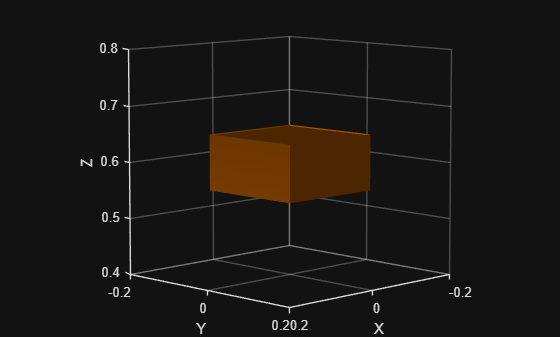

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

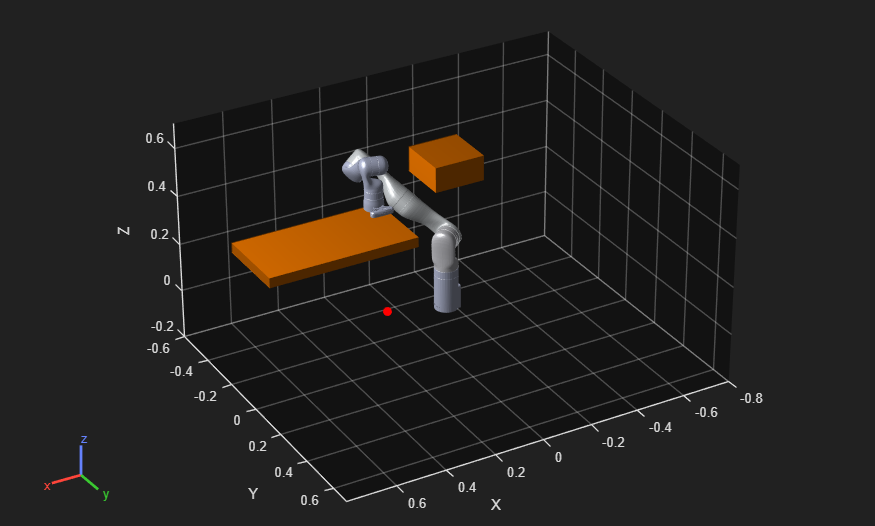

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

% pause;


$$\$$


Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 0.884626 seconds.


Qtheta = 219.5961

RAR = 43.1439

Elapsed time is 0.846888 seconds.


Qtheta = 218.8192

RAR = 43.1443

Elapsed time is 0.864514 seconds.


Qtheta = 219.9074

RAR = 43.1443

Elapsed time is 0.868449 seconds.


Qtheta = 210.3160

RAR = 43.1443

Elapsed time is 0.883661 seconds.


Qtheta = 216.9450

RAR = 43.1442

Elapsed time is 0.871632 seconds.


Qtheta = 216.5064

RAR = 43.1441

Elapsed time is 0.836540 seconds.


Qtheta = 211.5122

RAR = 43.1439

Elapsed time is 0.847597 seconds.


Qtheta = 211.6845

RAR = 43.1441

Elapsed time is 0.847074 seconds.


Qtheta = 210.2185

RAR = 43.1443

Elapsed time is 0.849536 seconds.


Qtheta = 207.7416

RAR = 43.1446

Elapsed time is 0.843835 seconds.


Qtheta = 207.0078

RAR = 43.1446

Elapsed time is 0.852153 seconds.


Qtheta = 208.2509

RAR = 43.1443

Elapsed time is 0.834190 seconds.


Qtheta = 208.6481

RAR = 43.1440

Elapsed time is 0.823616 seconds.


Qtheta = 208.0629

RAR = 43.1443

Elapsed time is 0.832805 seconds.


Qtheta = 202.6623

RAR = 43.1444

Elapsed time is 0.845945 seconds.


Qtheta = 198.4841

RAR = 43.1446

Elapsed time is 0.841705 seconds.


Qtheta = 197.6481

RAR = 43.1445

Elapsed time is 0.835521 seconds.


Qtheta = 193.9905

RAR = 43.1445

Elapsed time is 0.833910 seconds.


Qtheta = 193.3846

RAR = 43.1444

Elapsed time is 0.842638 seconds.


Qtheta = 187.9008

RAR = 43.1448

Elapsed time is 0.843123 seconds.


Qtheta = 186.2562

RAR = 43.1452

Elapsed time is 0.829599 seconds.


Qtheta = 182.0043

RAR = 43.1451

Elapsed time is 0.841082 seconds.


Qtheta = 180.0454

RAR = 43.1450

Elapsed time is 0.851481 seconds.


Qtheta = 175.3300

RAR = 43.1454

Elapsed time is 0.840661 seconds.


Qtheta = 173.8921

RAR = 43.1453

Elapsed time is 0.838703 seconds.


Qtheta = 170.6767

RAR = 43.1457

Elapsed time is 0.832526 seconds.


Qtheta = 170.5360

RAR = 43.1456

Elapsed time is 0.832974 seconds.


Qtheta = 169.4840

RAR = 43.1454

Elapsed time is 0.834267 seconds.


Qtheta = 168.0573

RAR = 43.1453

Elapsed time is 0.847124 seconds.


Qtheta = 161.4586

RAR = 43.1456

Elapsed time is 0.820391 seconds.


Qtheta = 154.5967

RAR = 43.1457

Elapsed time is 0.827259 seconds.


Qtheta = 148.0963

RAR = 43.1462

Elapsed time is 0.828873 seconds.


Qtheta = 140.5272

RAR = 43.1463

Elapsed time is 0.829615 seconds.


Qtheta = 134.1143

RAR = 43.1463

Elapsed time is 0.830903 seconds.


Qtheta = 132.2030

RAR = 43.1462

Elapsed time is 0.830230 seconds.


Qtheta = 124.6452

RAR = 43.1462

Elapsed time is 0.833396 seconds.


Qtheta = 114.7304

RAR = 43.1461

Elapsed time is 0.837998 seconds.


Qtheta = 110.8624

RAR = 43.1465

Elapsed time is 0.831945 seconds.


Qtheta = 99.3188

RAR = 43.1469

Elapsed time is 0.834610 seconds.


Qtheta = 97.4831

RAR = 43.1471

Elapsed time is 0.847894 seconds.


Qtheta = 96.1738

RAR = 43.1472

Elapsed time is 0.826284 seconds.


Qtheta = 85.5736

RAR = 43.1474

Elapsed time is 0.833086 seconds.


Qtheta = 78.2962

RAR = 43.1471

Elapsed time is 0.834862 seconds.


Qtheta = 74.5355

RAR = 43.1470

Elapsed time is 0.874205 seconds.


Qtheta = 62.5264

RAR = 43.1476

Elapsed time is 0.862680 seconds.


Qtheta = 55.5533

RAR = 43.1480

Elapsed time is 0.863243 seconds.


Qtheta = 51.7329

RAR = 43.1483

Elapsed time is 0.864360 seconds.


Qtheta = 49.2470

RAR = 43.1481

Elapsed time is 0.865677 seconds.


Qtheta = 49.5624

RAR = 43.1483

Elapsed time is 0.851234 seconds.


Qtheta = 48.3707

RAR = 43.1485

Elapsed time is 0.839059 seconds.


Qtheta = 47.4582

RAR = 43.1486

Elapsed time is 0.838850 seconds.


Qtheta = 47.2396

RAR = 43.1483

Elapsed time is 0.844606 seconds.


Qtheta = 46.2382

RAR = 43.1483

Elapsed time is 0.837783 seconds.


Qtheta = 46.2577

RAR = 43.1484

Elapsed time is 0.847579 seconds.


Qtheta = 46.5845

RAR = 43.1483

Elapsed time is 0.839793 seconds.


Qtheta = 45.6481

RAR = 43.1483

Elapsed time is 0.837533 seconds.


Qtheta = 45.2184

RAR = 43.1482

Elapsed time is 0.842379 seconds.


Qtheta = 45.2203

RAR = 43.1482

STOMP Finished.


isTrajectoryInCollision = logical
   1


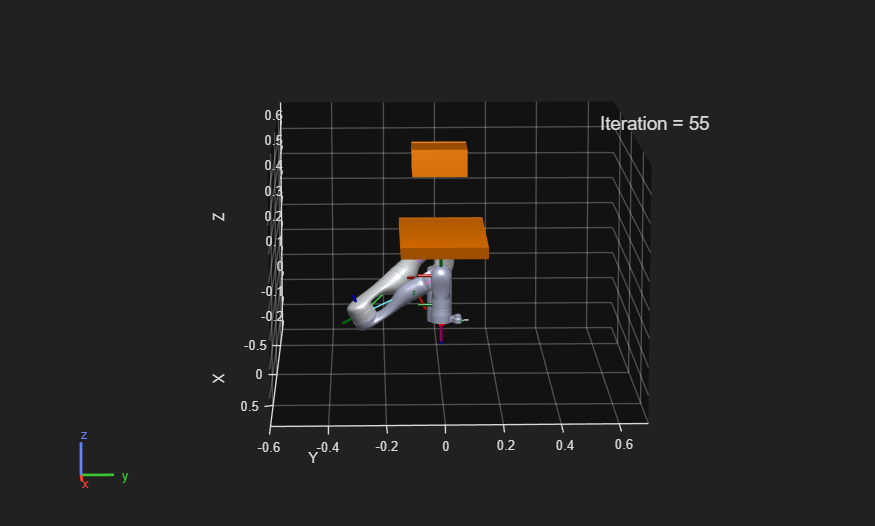

enableVideoTraining = 1;
enableVideo = 1;
helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.